3.1 전동기 구동에 있어서의 전압 제한. 

최대 출력전압 $V_{\textrm{smax}}$에 의해 제한된다. 

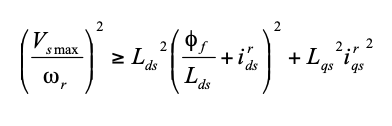

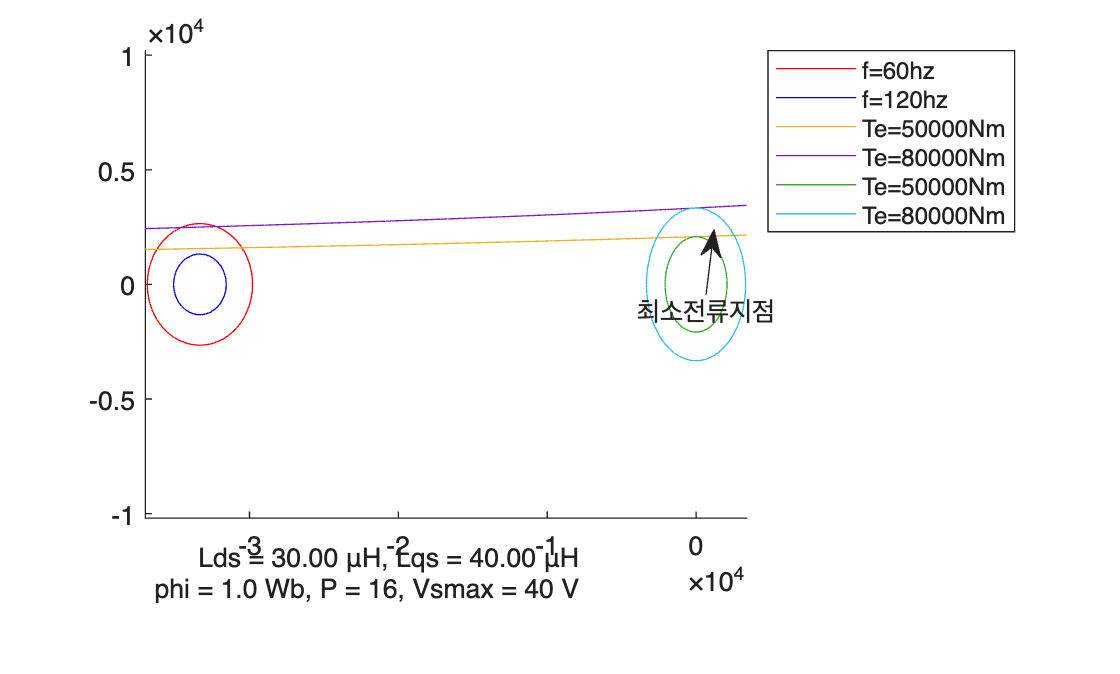


clear; close all;
syms Vds Vqs Vsmax
syms Ids Iqs Ismax
syms w Lqs Lds iqs ids phi;

% Vds = -w*Lqs*iqs
% Vqs =  w*Lds*ids + w*phi


eqn = (Vsmax/w)^2 == (phi+Lds*ids)^2 + (Lqs*iqs)^2;

eqn_plot1=subs(eqn, [    Lds     Lqs phi  Vsmax        w], ...
                    [0.03e-3 0.04e-3   1     40 2*pi*60]);
eqn_plot2=subs(eqn, [    Lds     Lqs phi  Vsmax        w], ...
                    [0.03e-3 0.04e-3   1     40 2*pi*120]);
figure; 
subplot(7, 1, [1 6]);hold on;

fimplicit(eqn_plot1,    'r', displayname='f=60hz');
fimplicit(eqn_plot2,    'b', displayname='f=120hz');

syms Te;
P = 16;
eqn = Te == 3/2*P * (ids*iqs*(Lds - Lqs) + phi*iqs);

eqn_plot3 = subs(eqn, [Te, phi,   Lds   Lqs], ...
                      [50000,   1, 30e-6 40e-6]);
eqn_plot4 = subs(eqn, [Te, phi,   Lds   Lqs], ...
                      [80000,   1, 30e-6 40e-6]);

fimplicit(eqn_plot3, displayname='Te=50000Nm');
fimplicit(eqn_plot4, displayname='Te=80000Nm');


% Lagrange 승수법을 사용해서 곡선과 원점 사이의 최단거리를 구한다.
eqn = rhs(eqn_plot3) -lhs(eqn_plot3); % 토크가 주어질 때 �방정식.
[ids_mn, iqs_mn, dist] = my_Lagrange_multiplier(eqn, ids, iqs);
fimplicit(ids^2+iqs^2==dist^2, displayname='Te=50000Nm')

eqn = rhs(eqn_plot4) -lhs(eqn_plot4); % 토크가 주어질 때 �방정식.
[ids_mn, iqs_mn, dist] = my_Lagrange_multiplier(eqn, ids, iqs);
fimplicit(ids^2+iqs^2==dist^2, displayname='Te=80000Nm')

axis([-37000 3400 -10200 10200])


legend('location', 'northeastoutside')
subplot(7, 1, 7); axis off;

param_str = sprintf(...
    'Lds = %.2f μH, Lqs = %.2f μH\n phi = %.1f Wb, P = %d, Vsmax = %.0f V', ...
    0.03e-3*1e6, 0.04e-3*1e6, 1, 16, 40);

text(0.5, 0.5, param_str, ...
    'HorizontalAlignment', 'right', ...
    'VerticalAlignment', 'middle', ...
    'FontSize', 10, ...
    'Interpreter', 'none');